This example demonstrates how to use KSSOLV to set up a simple silane SiH$_4$ molecule and call the scf function to compute the ground state energy and electron density of this molecule.

## Set the KSSOLV path

Once a MATLAB session has been started, we can issue the following command in the top directory of kssolv2.0 to properly set the path that contains the KSSOLV toolbox

KSSOLV_startup

## Construct a list of atoms

We first use the following commands to define two Atom objects contained in the silane molecule.

a1 = Atom('Si');
a2 = Atom('H');

These atoms are placed in an array called atomlist to be used later.

atomlist = [a1 a2 a2 a2 a2];

## Define the unit (super) cell

We specify the supercell that contains the molecule as a cubic cell with 10 Bohrs on each side. This is represented by a identity matrix. Each column of the matrix represent one Bravi lattice vector.

C = 10*eye(3);

## Define atomic coordinates

We now define the Cartesian coordinates for each of the atoms in the atomlist array.  This is done by multiplying an array that contains the fractional coordinates (often used for crystals) with the unit cell matrix C.

redxyz = [
 0.0     0.0      0.0
 0.161   0.161    0.161
-0.161  -0.161    0.161
 0.161  -0.161   -0.161
-0.161   0.161   -0.161
];
xyzlist = redxyz*C';

## Set up a Molecule object

With the basic elements defined above, we can now construct a Molecule object by using the Molecule constructor and passing in atomlist, supercell and atomic coordinates as key/value pairs. We can also define the planewave energy cutoff parameter that controls the number of planewaves used to represent the Kohn-Sham wavefunctions to be approximate. We can also optionally create a name for this molecule called 'SiH4'.

mol = Molecule('supercell',C, 'atomlist',atomlist, 'xyzlist' ,xyzlist, ...
      'ecutwfc',25, 'name','SiH4' );

## Run a SCF calculation

Once a Molecule object mol has been defined, we can then call the KSSOLV function scf with mol as the only argument.

[mol,H,X,info] = scf(mol);

The pseudopotential for H is loaded from C:\cygwin64\home\CYang\KSSOLV2.0\kssolv2.0\/ppdata/default/H_ONCV_PBE-1.0.upf
The pseudopotential for Si is loaded from C:\cygwin64\home\CYang\KSSOLV2.0\kssolv2.0\/ppdata/default/Si_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT


Beging SCF calculation for SiH4...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            1.027e-01
Total Energy    = -6.2378733880293e+00
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            1.966e-02
Total Energy    = -6.2539540217082e+00
SCF iter   3:
eigtol =   2.458e-03
Rel Vtot Err    =            5.542e-03
Total Energy    = -6.2541966382504e+00
SCF iter   4:
eigtol =   6.928e-04
Rel Vtot Err    =            1.991e-03
Total Energy    = -6.2542379470588e+00
SCF iter   5:
eigtol =   2.489e-04
Rel Vtot Err    =            6.803e-04
Total Energy    = -6.2542498282986e+00
SCF iter   6:
eigtol =   8.504e-05
Rel Vtot Err    =            4.120e-04
Total Energy    = -6.2542498064707e+00
SCF iter   7:
eigtol =   5.150e-05
Rel Vtot Err    =            6.542e-05
Total Energy    = -6.2542498377840e+00
SCF iter   8:
eigtol =   8.178e-06
Rel Vtot Err    =            2.621e-05
Total Energy    = -6.2542498380633e+00
SCF iter   9:
eigtol =   3.276e-06
Rel Vtot Err    =         

## Check the result

The function returns an updated Molecule object mol as well as a Hamiltonian object H, a Wavefunction object X and some additional information contained in a MATLAB structure name info above.

The updated mol contains atomic forces computed at the end of the SCF iteration

mol.xyzforce

ans =    -0.0000   -0.0000    0.0000
    0.0021    0.0021    0.0021
   -0.0021   -0.0021    0.0021
    0.0021   -0.0021   -0.0021
   -0.0021    0.0021   -0.0021


The Hamiltonian object H contain a number of data entries

H

H =   Ham with properties:

          n1: 46
          n2: 46
          n3: 46
        gkin: [6031×1 double]
       idxnz: [6031×1 double]
      idxnz2: []
        vion: [46×46×46 double]
      vnlmat: [6031×16 double]
     vnlsign: [16×1 double]
    ishybrid: 0
         rho: [46×46×46 double]
        vtot: [46×46×46 double]
         vnp: [46×46×46 double]
        vext: [46×46×46 double]
        vexx: []
       eband: [4×1 double]


In particular, it contains the approximation to the ground state electron density rho available at the end of the SCF iteration. We can visually examine the electron density by using the MATLAB isosurface command

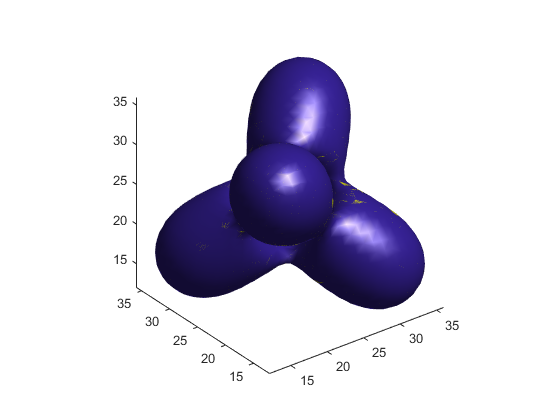

isosurface(fftshift(H.rho));
axis equal

The info structure contains the history of total energies and SCF errors computed at the end of each SCF iteration. We can plot the change of error by using

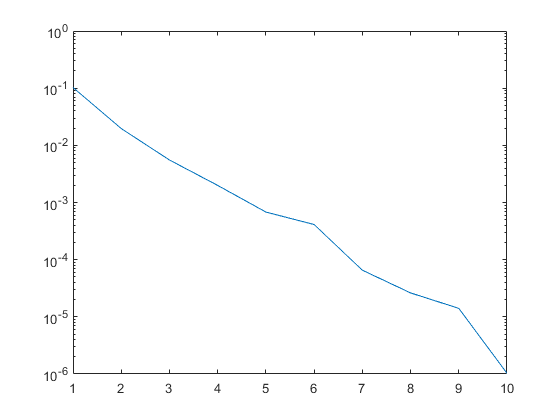

semilogy(info.SCFerrvec,'o-');